# L03: displaying and summarizing quantitative data

% Data: Wani's heart rate (beat per minute) data measured with his apple 
% watch for two weeks during this July (7/3 (Mon)-7/6 (Fri) and 7/10 (Mon) -7/14 
% (Fri), 9AM - 6PM)

## 1. import data

datdir =  '/Users/clinpsywoo/Dropbox/2011-yr/teaching/Stats_2018Fall/data';
dat = importdata(fullfile(datdir, 'health_data.xlsx'));


## 2. Draw histgram

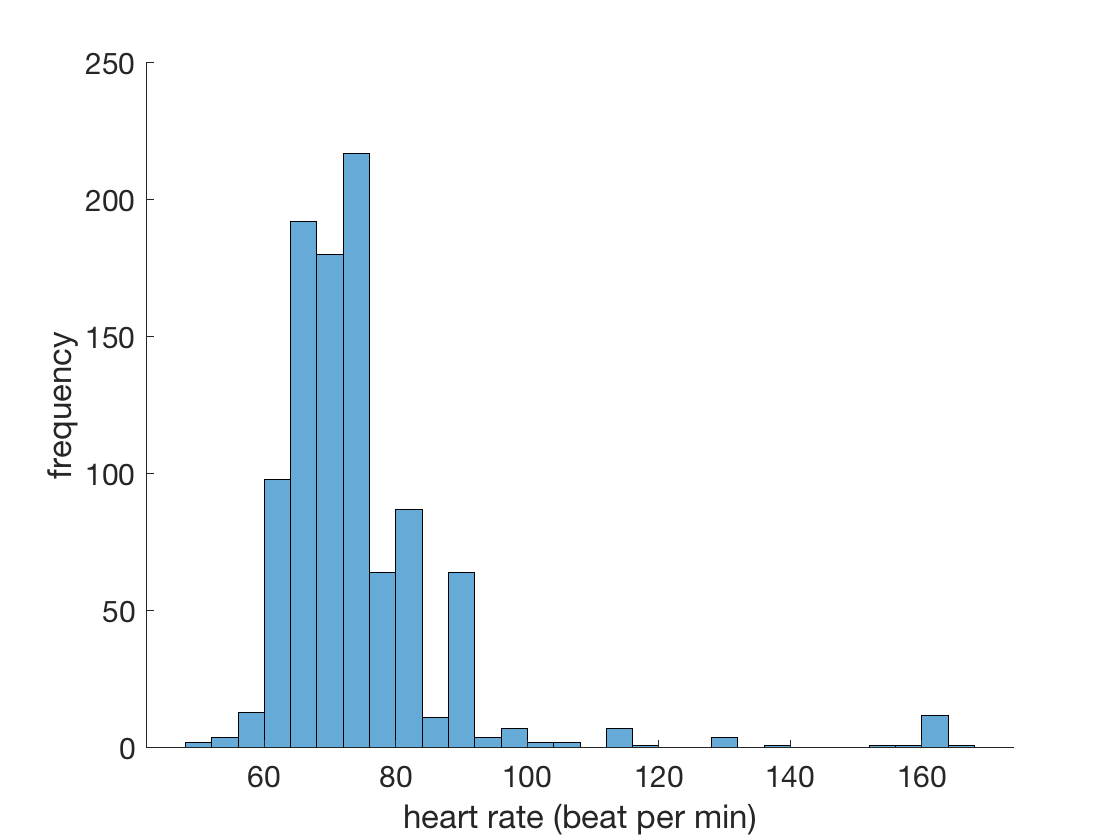

figure;
histogram(dat.data, 30)
xlabel('heart rate (beat per min)')
ylabel('frequency')
set(gca, 'fontsize', 15, 'box', 'off')

## 3. Draw a box plot

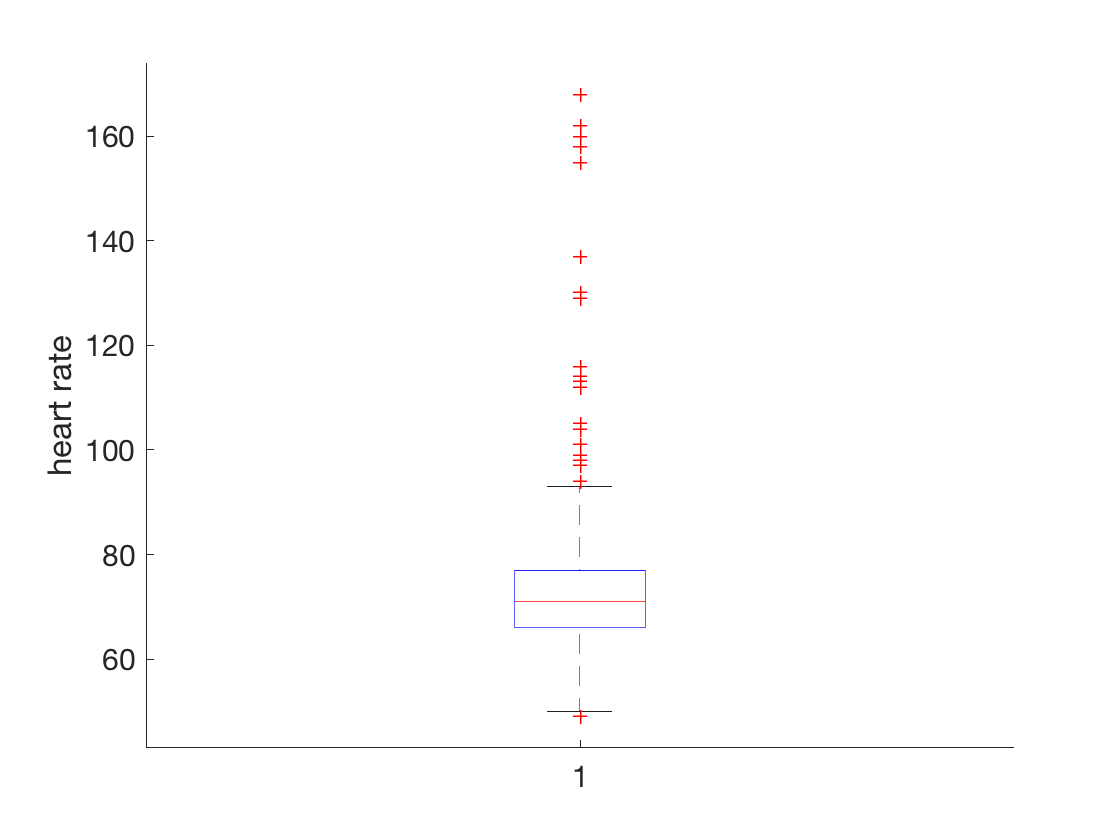

figure;
boxplot(dat.data);
set(gca, 'fontsize', 15, 'box', 'off')
ylabel('heart rate')

## 4. Median (orange vertical line) and Mean (red vertical line)

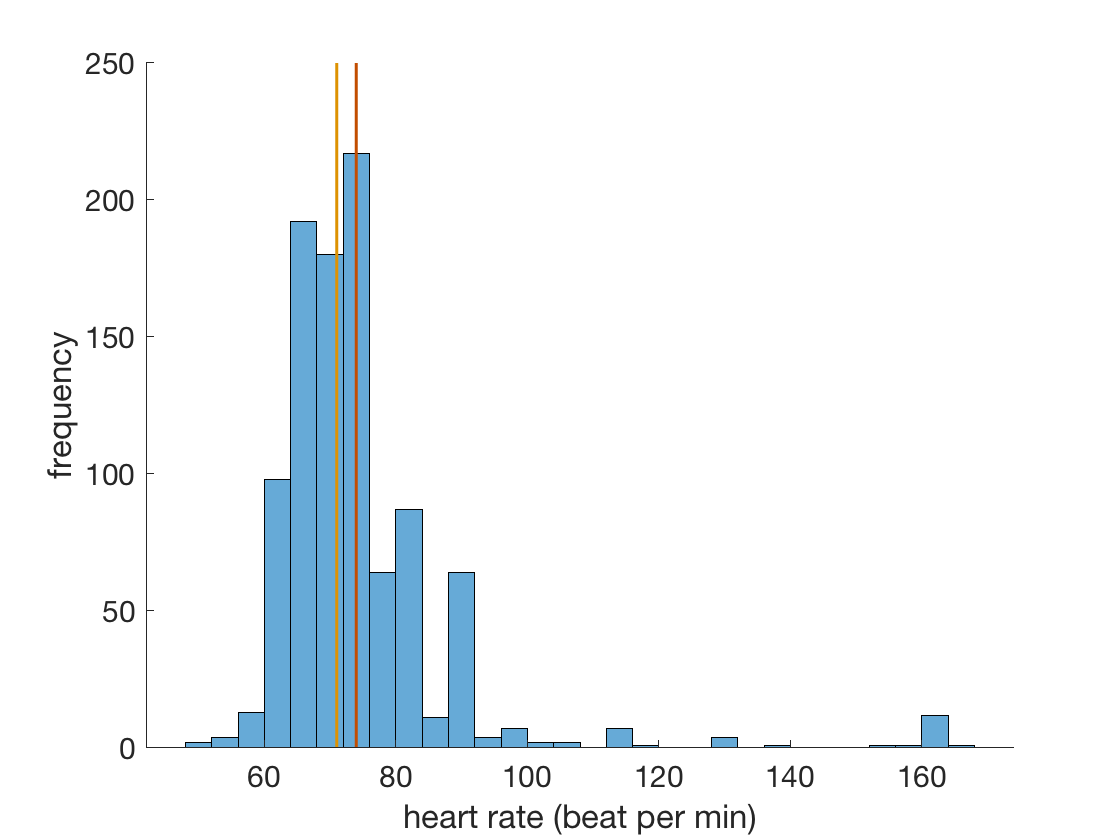

figure;
histogram(dat.data, 30)
line(repmat(mean(dat.data), 1, 2), get(gca, 'ylim'), 'color', [0.7608 0.3020 0], 'linewidth', 1.5);
line(repmat(median(dat.data), 1, 2), get(gca, 'ylim'), 'color', [0.8667 0.5725 0.0078], 'linewidth', 1.5)
xlabel('heart rate (beat per min)')
ylabel('frequency')
set(gca, 'fontsize', 15, 'box', 'off')

fprintf('\nMean = %.2f, Median = %.2f', mean(dat.data), median(dat.data));


Mean = 73.97, Median = 71.00

## 5. 5-Number summaries

Values = [max(dat.data); prctile(dat.data, 75); median(dat.data); prctile(dat.data, 25); min(dat.data)];
T = table(Values,'RowNames', {'Max';'Q3';'Median';'Q1';'Min'})

T = 5×1 table
              Values
              ______

    Max        168  
    Q3          77  
    Median      71  
    Q1          66  
    Min         49  


## 6. Mean and Standard deviation

fprintf('\nMean = %.2f, Standard deviation = %.2f', mean(dat.data), std(dat.data));


Mean = 73.97, Standard deviation = 14.66

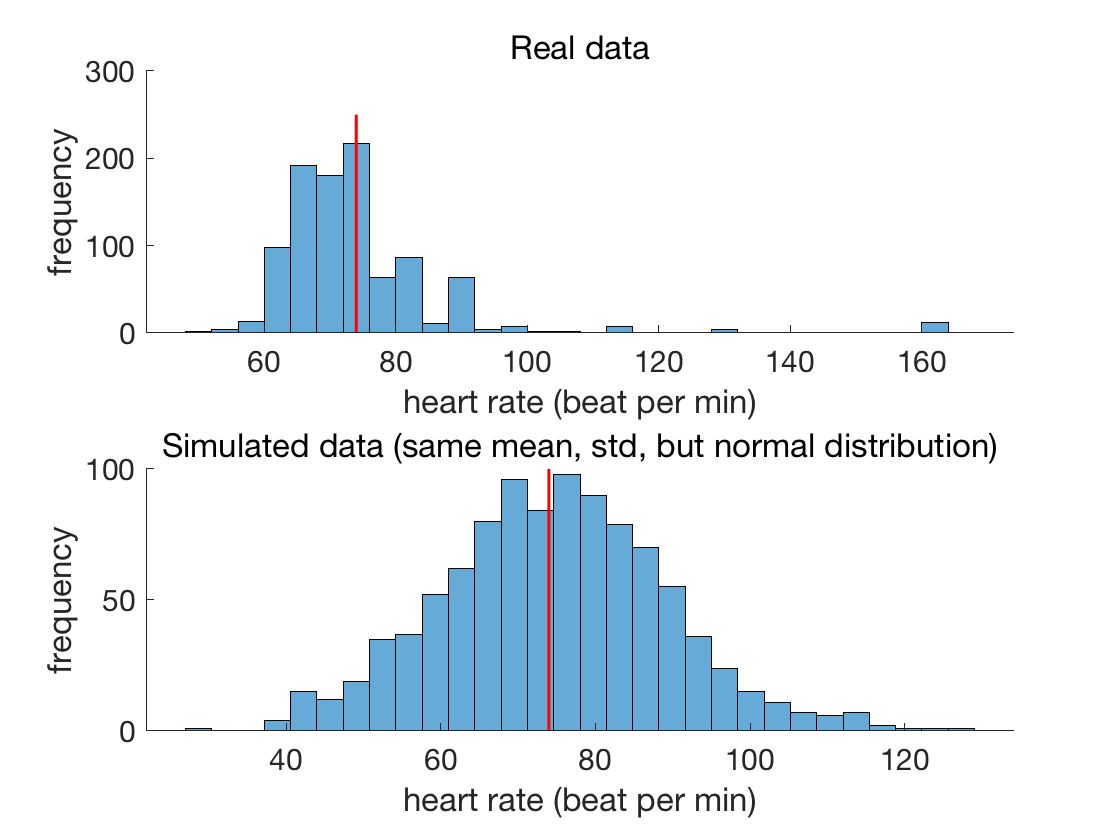

figure;
subplot(2,1,1);
histogram(dat.data, 30)
line(repmat(mean(dat.data), 1, 2), get(gca, 'ylim'), 'color', 'r', 'linewidth', 1.5)
xlabel('heart rate (beat per min)')
ylabel('frequency')
title('Real data')
set(gca, 'fontsize', 15, 'box', 'off');

subplot(2,1,2);
histogram(normrnd(mean(dat.data), std(dat.data), 1000, 1), 30)
line(repmat(mean(dat.data), 1, 2), get(gca, 'ylim'), 'color', 'r', 'linewidth', 1.5)
xlabel('heart rate (beat per min)')
ylabel('frequency')
title('Simulated data (same mean, std, but normal distribution)')
set(gca, 'fontsize', 15, 'box', 'off')